# RL Designer Guide: Warehouse Robot Navigation

## Step 1 : Prepare Environment Create Environment Class

Create warehourseEnv.m (class-based environment)

Create **moveRobot.m** 

rlCreateEnvTemplate("warehouseEnv")

env = warehouseEnv;
reset(env)

ans =      1     1


## 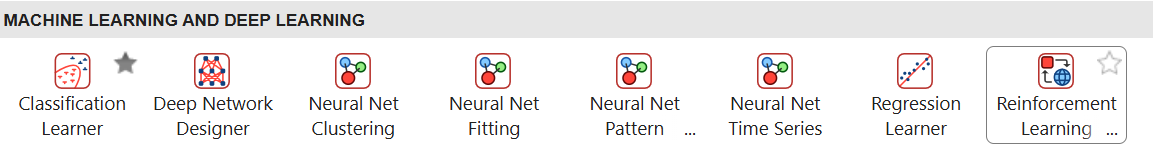

## Step 2: Import Environment เข้า RL Designer

- Open **Reinforcement Learning Designer**

- Click **Import > Environment > Select Environment**

- Select `env` →  Environment view show in panel 

## Step 3: Create Agent

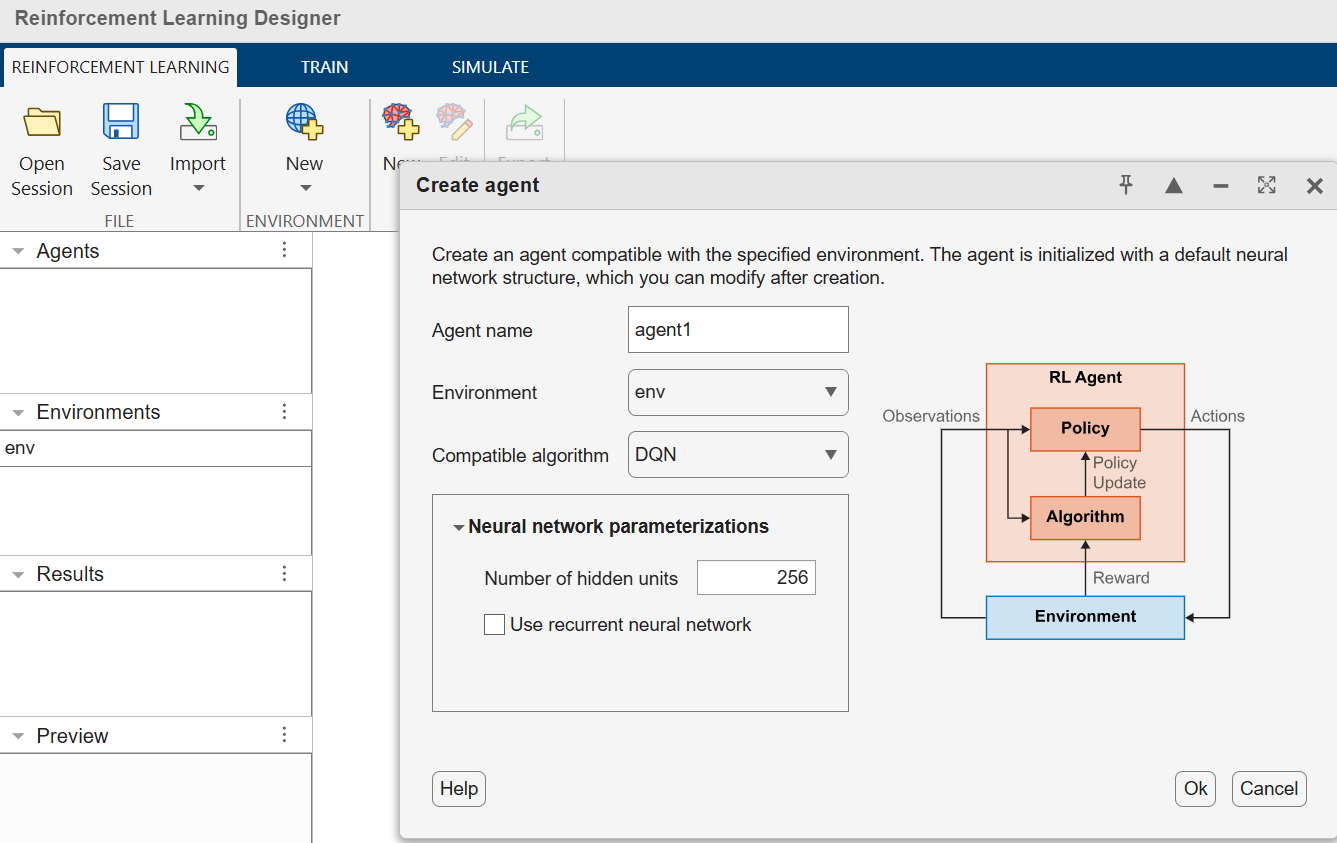

-  **New > Agent**

- Select:

- Environment → `env`

- Compatible algorithm → `DQN`

- Hidden units → `64` 

        3. Clicl **OK** → will see `agent1` in panel “Agents”

        4. Training Options:

                Max Episodes : 500

                Max Steps per episode : 50

                Stop Training Criteria: Average Reward > 15

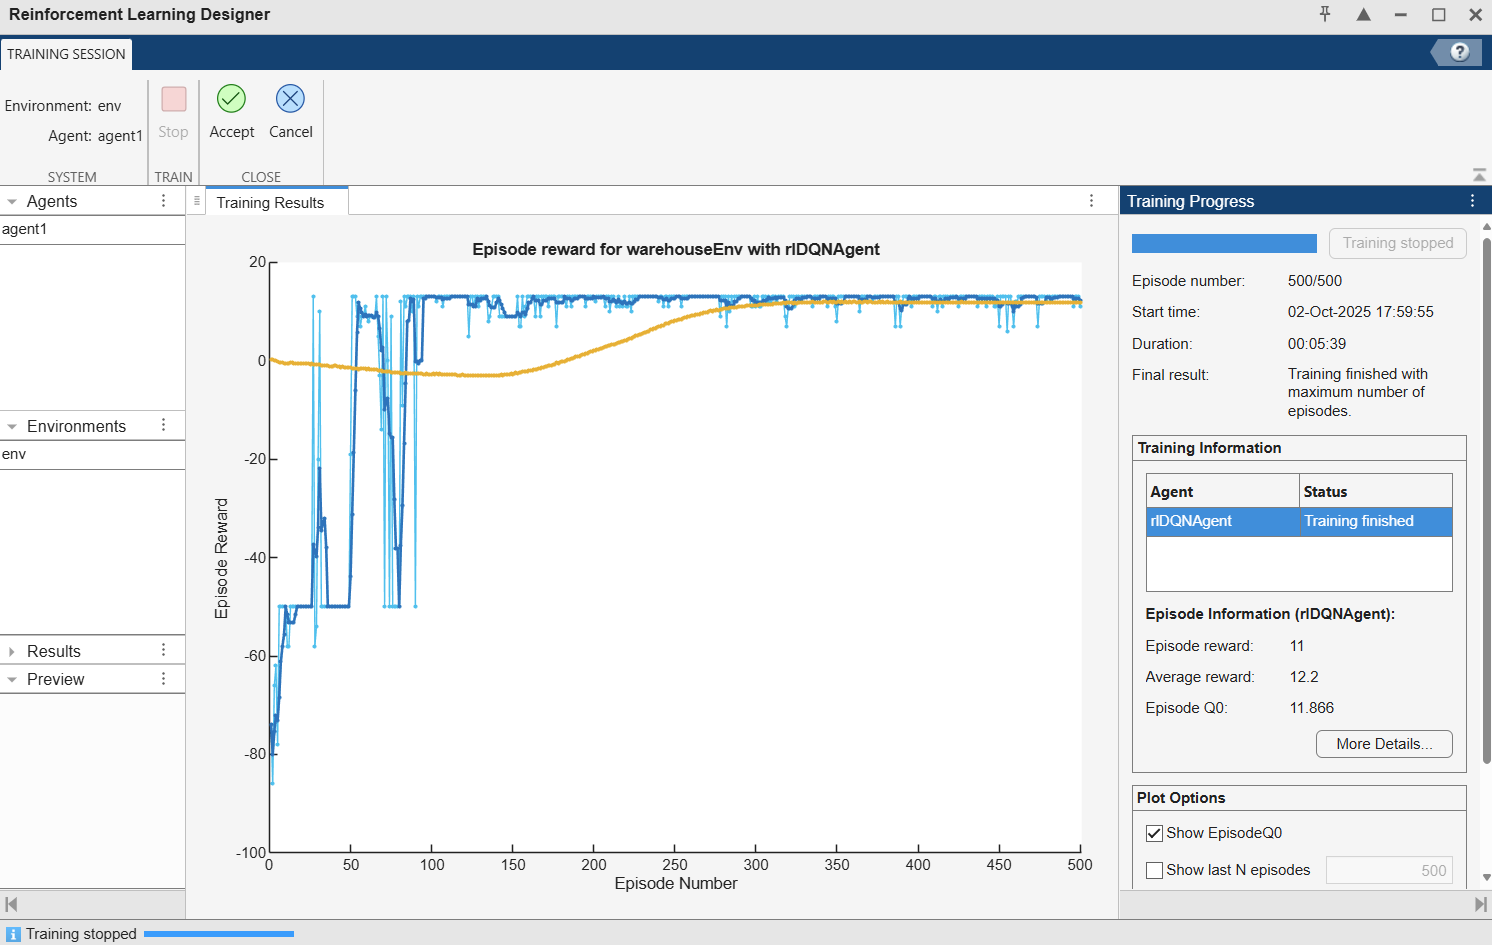

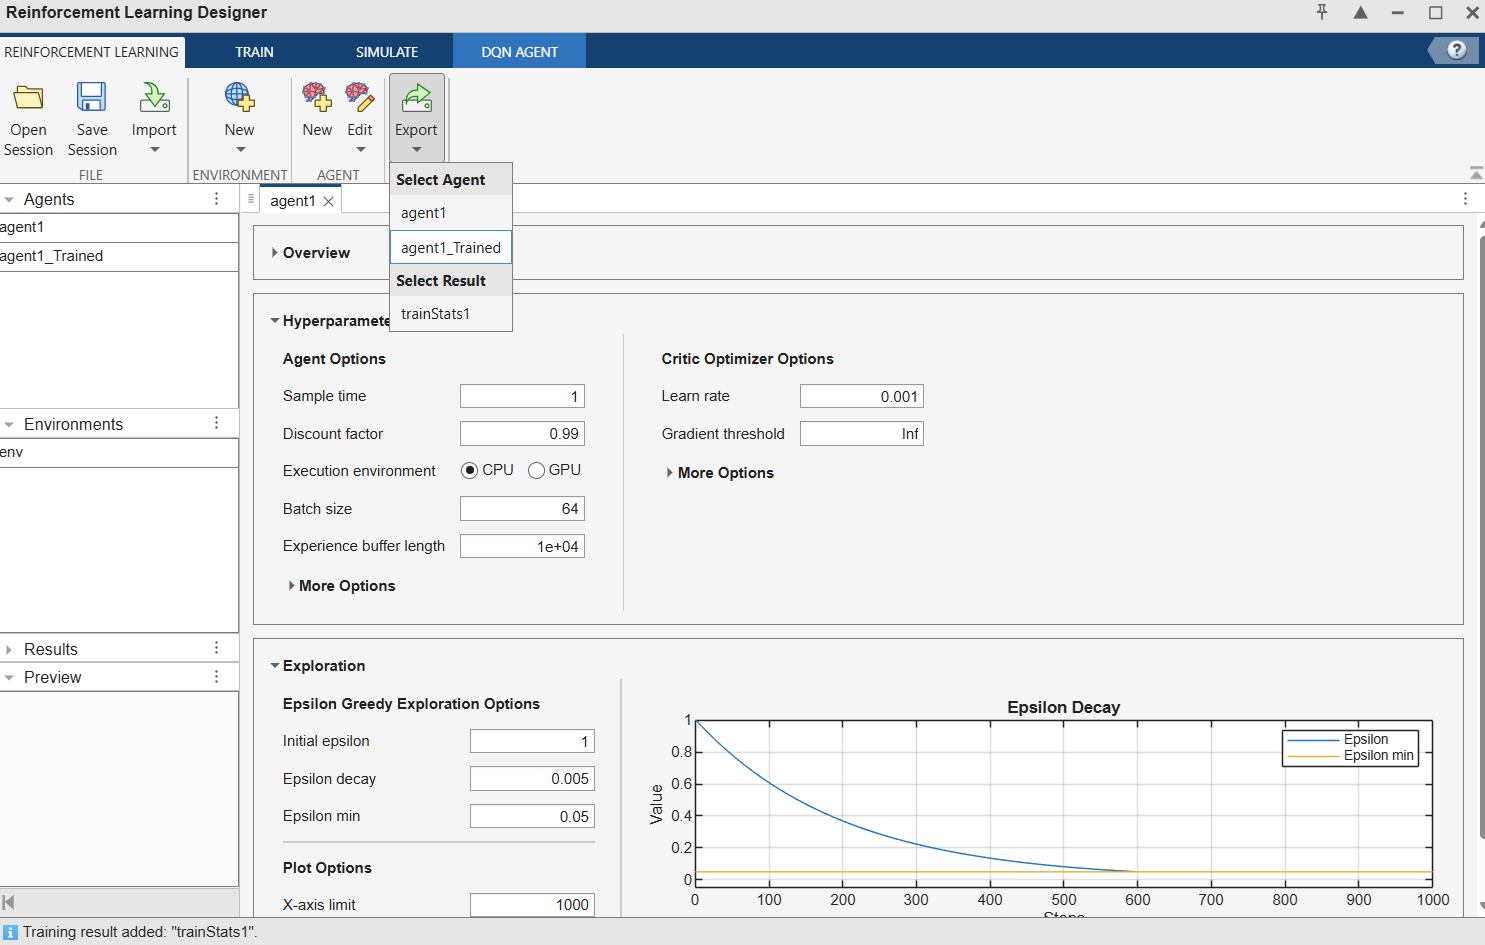

## Simulate Agent

**Simulate Agent **getAction + loop

% Reset environment
env = warehouseEnv; 
obs = reset(env);

% เก็บเส้นทาง
path = obs;

for step = 1:20
    % ใช้ policy ของ agent ที่ฝึกแล้ว
    act = getAction(agent1_Trained, obs);
    act = act{1};   % ดึงค่าออกจาก cell

    % เรียก step ของ environment โดยตรง
    [obs, reward, isDone, log] = env.step(act);

    % บันทึกเส้นทาง
    path = [path; obs];

    % แสดงผลลัพธ์แต่ละก้าว
    fprintf("Step %d: Action=%d -> State=[%d %d], Reward=%.1f\n", ...
            step, act, obs(1), obs(2), reward);

    if isDone
        disp("Goal reached!");
        break;
    end
end

Step 1: Action=4 -> State=[1 2], Reward=-1.0
Step 2: Action=4 -> State=[1 3], Reward=-1.0
Step 3: Action=4 -> State=[1 4], Reward=-1.0
Step 4: Action=4 -> State=[1 5], Reward=-1.0
Step 5: Action=2 -> State=[2 5], Reward=-1.0
Step 6: Action=2 -> State=[3 5], Reward=-1.0
Step 7: Action=2 -> State=[4 5], Reward=-1.0
Step 8: Action=2 -> State=[5 5], Reward=20.0


Goal reached!


% แสดงเส้นทางที่หุ่นยนต์เดิน
disp("Path followed by the agent:");

Path followed by the agent:


disp(path)

     1     1
     1     2
     1     3
     1     4
     1     5
     2     5
     3     5
     4     5
     5     5



3) Plot Update obstacles Auto

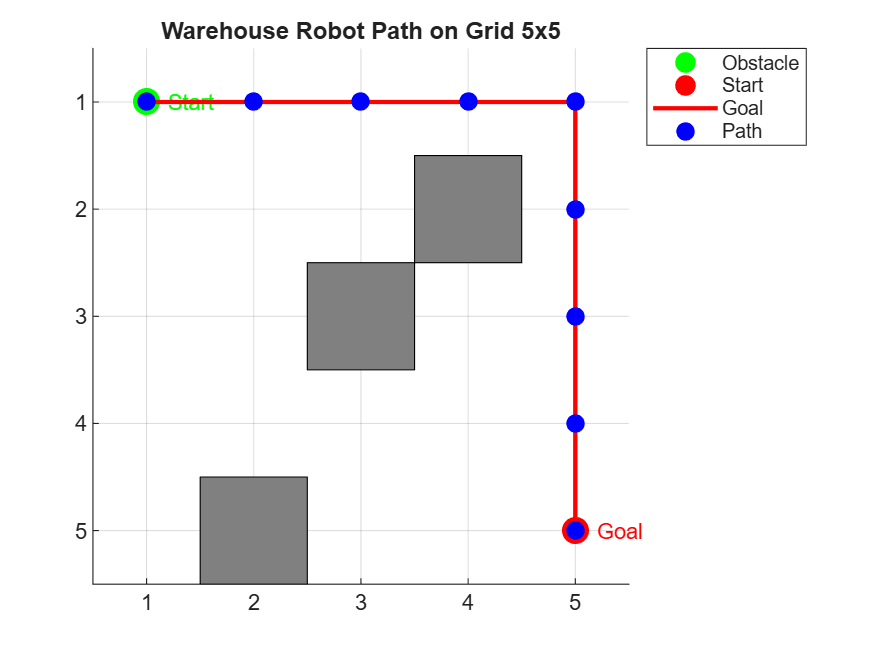

% Reset environment
env = warehouseEnv; 
obs = reset(env);

% เก็บเส้นทาง
path = obs;

for step = 1:20
    act = getAction(agent1_Trained, obs);
    act = act{1};   % ดึงค่าจาก cell
    [obs, reward, isDone, log] = env.step(act);
    path = [path; obs];
    if isDone
        break;
    end
end

% -------- Plot Grid --------
gridSize = env.GridSize;   % ดึงขนาดกริดจาก environment
startPos = [1 1];          % จุดเริ่มต้น
goalPos  = env.Goal;       % ดึงเป้าหมายจาก environment
obstacles = env.Obstacles; % ดึง obstacles อัตโนมัติจาก environment

figure; hold on; axis equal;
xlim([0.5 gridSize(2)+0.5]); ylim([0.5 gridSize(1)+0.5]);
set(gca,'YDir','reverse','XTick',1:gridSize(2),'YTick',1:gridSize(1));
grid on;

% วาด Obstacles จาก env.Obstacles
for k=1:size(obstacles,1)
    rectangle('Position',[obstacles(k,2)-0.5 obstacles(k,1)-0.5 1 1], ...
              'FaceColor',[0.5 0.5 0.5],'EdgeColor','k');
end

% วาด Start
plot(startPos(2), startPos(1), 'go', 'MarkerSize',12,'MarkerFaceColor','g');
text(startPos(2)+0.2,startPos(1),'Start','Color','g');

% วาด Goal
plot(goalPos(2), goalPos(1), 'ro', 'MarkerSize',12,'MarkerFaceColor','r');
text(goalPos(2)+0.2,goalPos(1),'Goal','Color','r');

% วาดเส้นทางของ agent
plot(path(:,2), path(:,1), 'r-', 'LineWidth',2);
plot(path(:,2), path(:,1), 'bo', 'MarkerSize',8,'MarkerFaceColor','b');

title('Warehouse Robot Path on Grid 5x5');
legend({'Obstacle','Start','Goal','Path'},'Location','bestoutside');